rosRead = ros2bagreader("bag_files/trapecio/rosbag2_2024_04_10-13_52_31/")

rosRead =   ros2bagreader with properties:

           FilePath: '/home/alogo/bag_files/trapecio/rosbag2_2024_04_10-13_52_31'
      AvailableBags: "rosbag2_2024_04_10-13_52_31_0.db3"
          StartTime: 1.7128e+09
            EndTime: 1.7128e+09
    AvailableTopics: [1×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [1107×3 table]
        NumMessages: 1107


Messages = readMessages(rosRead)

Messages = 1107×1 cell array
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}


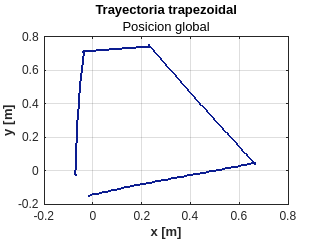


X_Glob = zeros(length(Messages), 1);
Y_Glob = zeros(length(Messages), 1);

for i=1:length(Messages)
    X_Glob(i) = Messages{i,1}.x;
    Y_Glob(i) = Messages{i,1}.y;
end

figure(1)
plot(X_Glob,Y_Glob, LineWidth=1.5, Color="#0C1D91")
title("Trayectoria trapezoidal")
subtitle("Posicion global")
xlabel("x [m]",FontWeight="bold")
ylabel("y [m]",FontWeight="bold")
grid on